# Create object imageDatastore

path =fullfile(matlabroot,'toolbox','nnet','nndemos','nndatasets','DigitDataset');
imds = imageDatastore(path,'IncludeSubfolders',true,'LabelSource','foldernames');
imds.countEachLabel;
% split each labels, 800 for train and 200 for test
[train, test] = imds.splitEachLabel(0.8,'randomize');

## Network

layers = [imageInputLayer([28, 28]), ...
    convolution2dLayer(5,20),reluLayer,    maxPooling2dLayer(2,'Stride',2),...
    fullyConnectedLayer(10),    softmaxLayer,    classificationLayer];

## Optimization options

ops = trainingOptions('sgdm','InitialLearnRate',0.5,'MaxEpochs',10,'Plots','training-progress',...
    'GradientThreshold',5);
% ops = trainingOptions('sgdm','MaxEpochs',10, 'InitialLearnRate',0.0005,...
     %'Plots','training-progress')

## train Networks

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


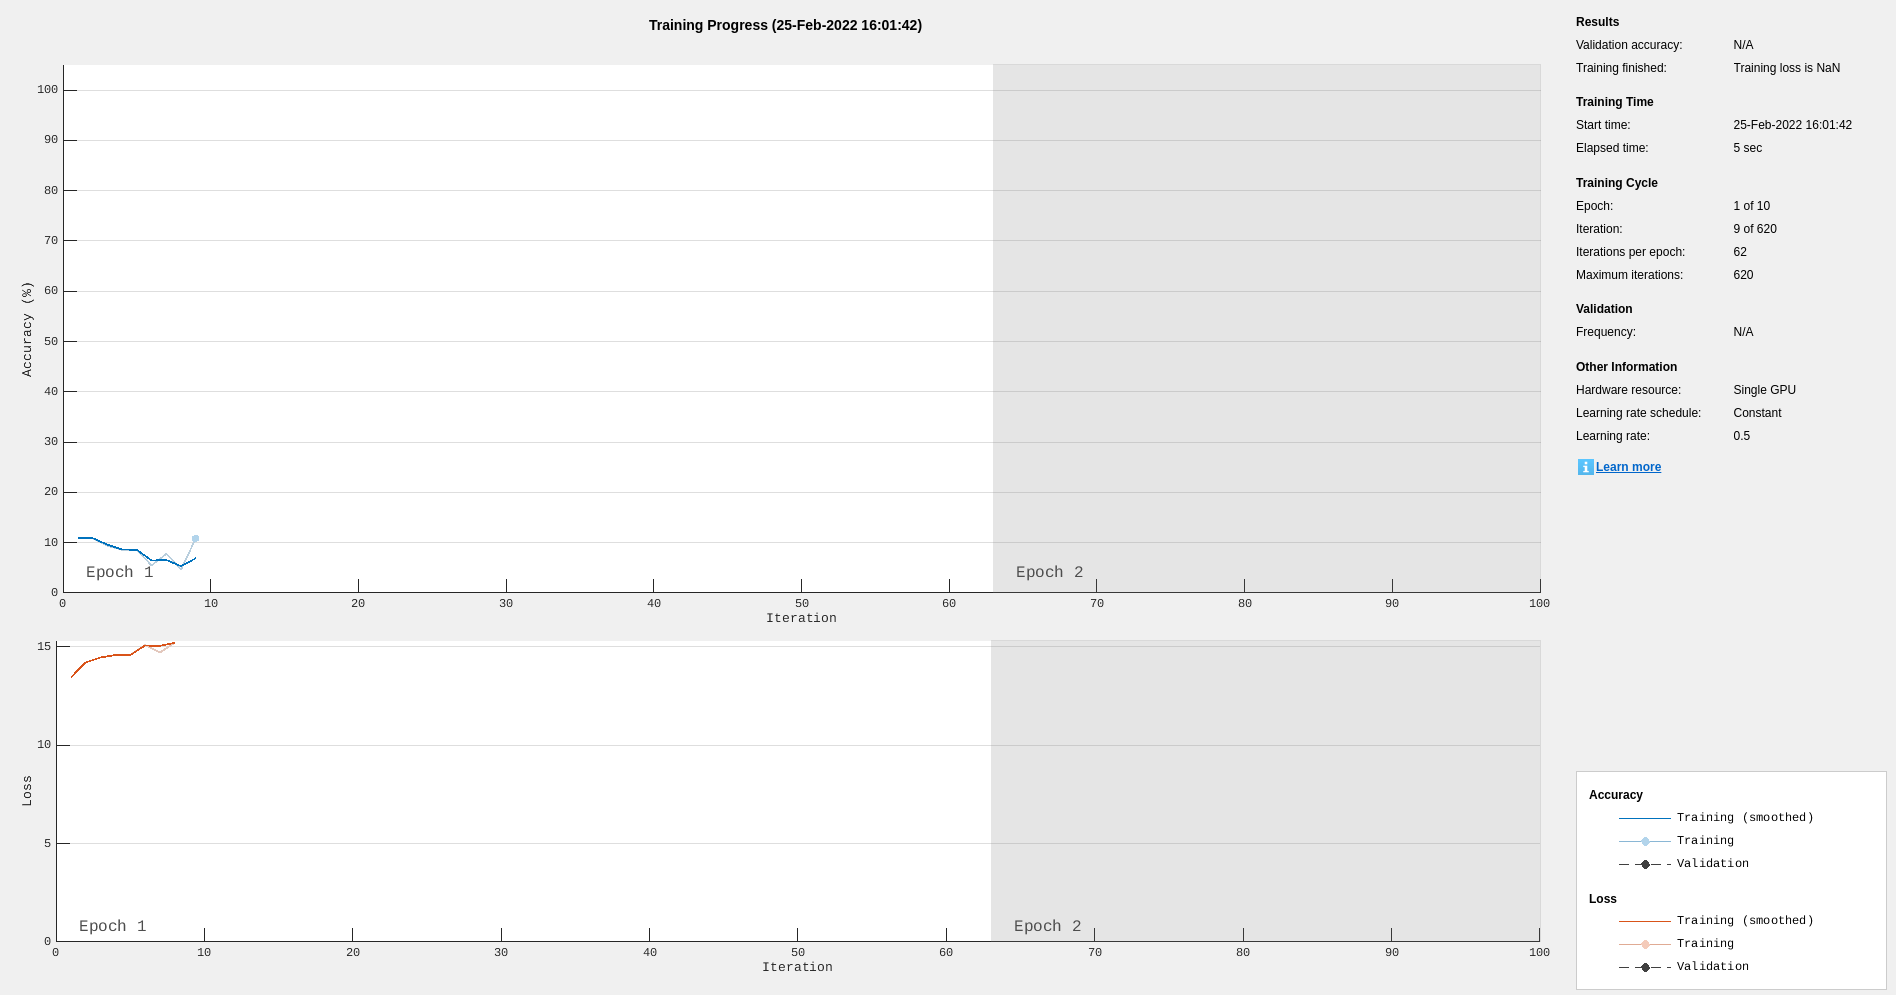

net = trainNetwork(train,layers,ops);

c = classify(net,test);
l = test.Labels;
sum(c==l)/numel(l)

ans = 0